clc
clf
clear all
close all
rng(0)

% x = [0.0015,     0.0078, 1.1478e-05]
% x = [0.0012,     0.0085, 2.8630e-04]
% x = [0.0161,     0.0571, 0.0068]
% x = [0.0154,     0.0485, 3.0626e-05]
% x = [8.6984e-04, 0.0093, 3.0196e-04]
% x = [0.0010,     0.0054, 1.5093e-05]
% x = [0.0140,     0.0772, 1.8592e-04]
% x = [6.6951e-04, 0.0073, 1.1012e-05]
% x = [3.5153e-04, 0.0029, 0.0012]
% x = [0.0026,     0.0115, 1.1682e-05]

ans = 5.2000

ans = 6.8333

ans = 3.1494

# Induction Machine + MMCC Simulation

## Current topology: M2C

## Parameters

Simulation and control steps

Tf = 2;        % Total simulation time
fs = 6e3;
Ts = 1/fs        % Sampling time

Ts = 1.6667e-04

Ns = ceil(Tf/Ts) % Number of sampling steps

Ns = 12000

Ni = 40;         % Number of integration steps between each ISR (Interrupt Service Routine)
Ti = Ts/Ni	     % Integration step

Ti = 4.1667e-06

Tsim = linspace(0, Tf, Ns);

Topology = 'M2C';

Vdc = 4 * 130;

Ax_max = Vdc / 2;
Ay_max = 380 * sqrt(2 / 3) * 25 / 50

Ay_max = 155.1344

wx0 = 0;
wy_max = 25 * 2*pi;

ix_max = 4.2;
iy_max = 4.5;
is_max = 8.5;
vB_max = Ax_max + Ay_max

vB_max = 415.1344

vc_mean_ref = Vdc;
vo_max = vc_mean_ref - vB_max

vo_max = 104.8656

VCdiff = 10/100; % Max. cap. voltage deviation ratio, used for training

Max. input/output power

ix_max * Ax_max * 2 % dc input

ans = 2184

iy_max * Ay_max * 3 % 3-ph output

ans = 2.0943e+03

Cluster current oversizing

eta = is_max / (ix_max / 2 + iy_max / 3) - 1

eta = 1.3611

## Reference Frame Transforms (RFT)

RFT = reference_frame_transforms();

## Modular Multilevel Cascaded Converter (MMCC)

Specifications

specsMMCC = struct();

specsMMCC.Topology = Topology; % Converter topology M3C/M2C
specsMMCC.Ti       = Ti;       % Integration step
specsMMCC.Rb       = 0.2;      % Branch resistance
specsMMCC.Lb       = 5e-3;     % Branch inductance
specsMMCC.Csm      = 987e-6;   % Submodule capacitance
specsMMCC.Nsm      = 4;        % Submodules per cluster
specsMMCC.Rx       = 0* 1e-3;     % Input filter resistance
specsMMCC.Lx       = 0* 0.1e-3;   % Input filter inductance
specsMMCC.Ry       = 0* 1;        % Output load resistance
specsMMCC.Ly       = 0* 200e-3;   % Output load inductance

Initial values

init_valsMMCC = struct();

if strcmp(Topology, 'M3C')
    init_valsMMCC.is0 = zeros(9, 1);                     % Cluster current
    init_valsMMCC.vc0 = (vB_max + vo_max) * ones(9, 1);  % Cluster capacitor voltage
elseif strcmp(Topology, 'M2C')
    init_valsMMCC.is0 = zeros(6, 1);                     % Cluster current
    init_valsMMCC.vc0 = (vB_max + vo_max) * ones(6, 1);  % Cluster capacitor voltage
end

Create object

MMCC = ClassMMCC(specsMMCC, init_valsMMCC);

## Induction Machine (IM)

Specifications

specsIM = struct();

specsIM.Ti = Ti;

Initial values

init_valsIM = struct();

init_valsIM.w0         = 0;
init_valsIM.Magnetized = false;

Create object

IM = ClassIM(specsIM, init_valsIM);

## Induction Machine Voltage Estimator

Specifications

specsIMVE = struct();

specsIMVE.IM  = IM;
specsIMVE.RFT = RFT;

Create object

IMVE = IM_voltage_estimator(specsIMVE);

## Input Grid

Specifications

specsGrid = struct();

specsGrid.Ti       = Ti;
specsGrid.Topology = Topology;
specsGrid.GridType = 'in';

Initial values

init_valsGrid = struct();

init_valsGrid.Ax0 = Ax_max;

Create object

Grid = ClassGrid(specsGrid, init_valsGrid);

## Coupled MMCC + IM system

Specifications

specsSystem = struct();

specsSystem.Ti     = Ti;
specsSystem.RFT    = RFT;
specsSystem.MMCC   = MMCC;
specsSystem.IM     = IM;
specsSystem.Grid   = Grid;

Create object

sys = ClassSystem(specsSystem);

## Phase Locked Loops (PLL)

[ImperixPLL](https://imperix.com/doc/implementation/synchronous-reference-frame-pll)

Specifications

xi_pll = 1/sqrt(2);
wc_pll = 100*2*pi;

specsPLL = struct();

specsPLL.Ts    = Ts;
specsPLL.kp    = 2*xi_pll*wc_pll;
specsPLL.ki    = wc_pll^2;
specsPLL.u_min = -Inf;
specsPLL.u_max = Inf;

Create objects

PLLx = ClassPLL(specsPLL);
PLLy = ClassPLL(specsPLL);

## TEB PI and Filter design

Plant model

% (Mean cluster capacitor voltage)/(Input current) transfer function
if strcmp(MMCC.Topology, 'M3C')
    k_teb = Ax_max / (6 * vc_mean_ref) / MMCC.C;
elseif strcmp(MMCC.Topology, 'M2C')
    k_teb = Ax_max / (3 * vc_mean_ref) / MMCC.C;
end
G_teb = k_teb * tf(1, [1, 0]);

Closed loop poles assignment (one first and one second order poles)

% Second order pole
xi_acl    = 1 / sqrt(2); % Damping factor
wn_acl    = 2 * pi * 15; % Natural frequency
% First order pole
alpha_acl = 2 * pi * 30; % Natural frequency

% PI
kp_teb   = wn_acl*(wn_acl+2*xi_acl*alpha_acl)/(k_teb*(2*wn_acl*xi_acl+alpha_acl));
ki_teb   = wn_acl^2*alpha_acl/(k_teb*(2*wn_acl*xi_acl+alpha_acl));
% Filter
wn_filt = 2*wn_acl*xi_acl+alpha_acl;

## Low Pass Filter for Mean Energy (LPF)

Specifications

specsLPF = struct();

specsLPF.Ts = Ts;
specsLPF.wn = wn_filt;

Initial values

init_valsLPF = struct();

init_valsLPF.y0 = mean(MMCC.vc);

Create object

LPF = ClassLPF(specsLPF, init_valsLPF);

## Total Energy Balance Proportional Integral Controller (PI_teb)

Specifications

specsPI = struct();

specsPI.Ts    = Ts;
specsPI.kp    = kp_teb;
specsPI.ki    = ki_teb;
specsPI.u_min = -ix_max;
specsPI.u_max = ix_max;

Create object

PI_teb = ClassPI(specsPI);

## Field Oriented Control (PI_F, PI_w)

Specifications

% Flux
wn_F = 2 * pi * 10;
xi_F = 1 / sqrt(2);
% PI
kp_F = (2 * xi_F * wn_F * IM.tau_r - 1) / IM.Lm;
ki_F = wn_F^2 * IM.tau_r / IM.Lm;
comp_F = 1;
% % P
% kp_F = wn_F * IM.tau_r / IM.Lm - 1
% ki_F = 0
% comp_F = (kp_F + 1) / kp_F

specsPI_F = struct();

specsPI_F.Ts    = Ts;
specsPI_F.kp    = kp_F;
specsPI_F.ki    = ki_F;
specsPI_F.u_min = -iy_max;
specsPI_F.u_max = iy_max;

% Speed PI
xi_w = 1 / sqrt(2);
wn_w = wn_F * 0.8;
cw   = IM.kT * IM.FrN * IM.np / IM.J / 10;
kp_w = 2 * xi_w * wn_w / cw;
ki_w = wn_w^2 / cw;

specsPI_w = struct();

specsPI_w.Ts    = Ts;
specsPI_w.kp    = kp_w;
specsPI_w.ki    = ki_w;
specsPI_w.u_min = -iy_max;
specsPI_w.u_max = iy_max;

Create objects

PI_F = ClassPI(specsPI_F);
PI_w = ClassPI(specsPI_w);

## Cluster Energy Model Predictive Controller (CEMPC)

Cluster energy and capacitor voltage references

Ec_mean_ref = MMCC.C/2 * vc_mean_ref^2;

vc_ref = vc_mean_ref * ones(MMCC.m, 1);
Ec_ref = Ec_mean_ref * ones(MMCC.m, 1);

Specifications

specsCEMPC = struct();

specsCEMPC.Ts          = Ts;
specsCEMPC.MMCC        = MMCC;
specsCEMPC.is_max      = is_max;
specsCEMPC.vo_max      = vo_max;
specsCEMPC.Ec_mean_ref = Ec_mean_ref;
specsCEMPC.vc_mean_ref = vc_mean_ref;

% specsCEMPC.lambda_z  = 1e-2 * 3;
% specsCEMPC.lambda_o  = 1e-2 * 12.5;
% specsCEMPC.lambda_z  = 1e-2 * 2;
% specsCEMPC.lambda_o  = 1e-2 * 7.5;
% specsCEMPC.lambda_z  = 1e-2 * 1;
% specsCEMPC.lambda_o  = 1e-2 * 5;
% specsCEMPC.lambda_z  = 1e-2 * 0.5;
% specsCEMPC.lambda_o  = 1e-2 * 1.25;
% specsCEMPC.lambda_z  = 1e-2 * 0.1;
% specsCEMPC.lambda_o  = 1e-2 * 1.25;
% specsCEMPC.lambda_z  = 1e-2 * 0.05;
% specsCEMPC.lambda_o  = 1e-2 * 1.25;
% specsCEMPC.lambda_z  = 1e-2 * 0.01;
% specsCEMPC.lambda_o  = 1e-2 * 0.5;
% specsCEMPC.lambda_z  = 1e-2 * 0.005;
% specsCEMPC.lambda_o  = 1e-2 * 0.5;
% specsCEMPC.lambda_z  = 1e-2 * 0.001;
% specsCEMPC.lambda_o  = 1e-2 * 0.375;

% specsCEMPC.lambda_z = 7.0146e-05;
% specsCEMPC.lambda_o = 1.0498e-05;

% specsCEMPC.lambda_z = 0.00011738;
% specsCEMPC.lambda_o = 1.8795e-05;

% specsCEMPC.lambda_z = 0.00010221;
% specsCEMPC.lambda_o = 0.00015294;

% specsCEMPC.lambda_z = 5.7561e-05;
% specsCEMPC.lambda_o = 1.2249e-05;

% specsCEMPC.lambda_z = 0.0014797;
% specsCEMPC.lambda_o = 0.0078478;

specsCEMPC.lambda_z = x(1);
specsCEMPC.lambda_o = x(2);

specsCEMPC.Nl        = 20;
specsCEMPC.Np        = 10;

Create object

CEMPC = ClassCEMPC(specsCEMPC);

## Basic Variables Predictor (Predictor)

Predict external voltages and currents for the Cluster Energy MPC

Specifications

specsPredictor = struct();

specsPredictor.MMCC  = MMCC;
specsPredictor.CEMPC = specsCEMPC;
specsPredictor.RFT   = RFT;

Create object

Predictor = BasicVariablesPredictor(specsPredictor);

## Cluster Current Model Predictive Controller (CCMPC)

Specifications

% Model for control
specsMMCC_CC = specsMMCC;
specsMMCC_CC.Ti = Ts;
MMCC_CC = ClassMMCC(specsMMCC_CC, init_valsMMCC);

specsCCMPC = struct();

specsCCMPC.Ts          = Ts;
specsCCMPC.MMCC        = MMCC_CC;
specsCCMPC.is_max      = is_max;
specsCCMPC.ix_max      = ix_max;
specsCCMPC.iy_max      = iy_max;
specsCCMPC.zB_ratio    = 0.5;
specsCCMPC.vc_mean_ref = vc_mean_ref;
% specsCCMPC.lambda   = 1e-2 * 1;
% specsCCMPC.lambda   = 1e-2 * 100;

% specsCCMPC.lambda = 0.00013654;

% specsCCMPC.lambda = 1.0226e-05;

% specsCCMPC.lambda = 0.00099695;

% specsCCMPC.lambda = 1.2473e-04;

% specsCCMPC.lambda = 1.1478e-05;

specsCCMPC.lambda = x(3);

Create object

CCMPC = ClassCCMPC(specsCCMPC);

## Cluster voltage steady state reference generator

Specifications

specsRefGen = struct();

specsRefGen.MMCC = MMCC_CC;
specsRefGen.RFT  = RFT;

Create object

vsRefGen = vsRefGenerator(specsRefGen);

## Buffer

Specifications

specsBuffer = struct();

specsBuffer.Ts   = Ts;
specsBuffer.Ns   = Ns;
specsBuffer.Tsim = Tsim;
specsBuffer.MMCC = MMCC;
specsBuffer.Np   = CEMPC.Np;

Create object

buffer = ClassBuffer(specsBuffer);

# Simulation

Reset

buffer = buffer.reset();

sys    = sys.reset();
PLLx   = PLLx.reset();
PLLy   = PLLy.reset();
LPF    = LPF.reset();
PI_teb = PI_teb.reset();
PI_w   = PI_w.reset();
PI_F   = PI_F.reset();
CEMPC  = CEMPC.reset();
CCMPC  = CCMPC.reset();

Maneuver

w_ref_vec = zeros(Ns, 1);

w_ref_ini = 0;
w_ref_fin = 2*pi*25 / IM.np;

t_ini = 0.5;
t_fin = 1.5;

mask = Tsim <= t_ini;
w_ref_vec(mask) = w_ref_ini;

mask = and(t_ini < Tsim, Tsim <= t_fin);
w_ref_vec(mask) = linspace(w_ref_ini, w_ref_fin, sum(mask));

mask = t_fin <= Tsim;
w_ref_vec(mask) = w_ref_fin;

% mask = Tsim <= 1;
% w_ref_vec(mask) = w_ref_ini;
% 
% mask = and(1 < Tsim, Tsim <= 2);
% w_ref_vec(mask) = linspace(w_ref_ini, w_ref_fin, sum(mask));
% 
% mask = and(2 < Tsim, Tsim <= 3);
% w_ref_vec(mask) = w_ref_fin;
% 
% mask = and(3 < Tsim, Tsim <= 4);
% w_ref_vec(mask) = linspace(w_ref_fin, -w_ref_fin, sum(mask));
% 
% mask = and(4 < Tsim, Tsim <= 5);
% w_ref_vec(mask) = -w_ref_fin;
% 
% mask = 5 <= Tsim;
% w_ref_vec(mask) = 0;

t_mag = 0.3;
isd_ref_vec = zeros(1, Ns);
isd_ref_vec(Tsim <= t_mag) = linspace(0, IM.isdN, sum(Tsim <= t_mag));
isd_ref_vec(t_mag <= Tsim) = IM.isdN;

Run

% Initialize progress bar
h = waitbar(0, 'Simulating...');

for ts = 1:Ns

%% Measure
% External voltages
vxy = sys.vxy; vx = vxy(1:MMCC.p); vy = vxy(MMCC.p+1:end);
vB  = MMCC.A' * vxy;
% Cluster currents
is  = sys.MMCC.is;
ixy = MMCC.A * is; ix = ixy(1:MMCC.p); iy = ixy(MMCC.p+1:end);
iB  = MMCC.pinvA * ixy;
iz  = is - iB;
ie  = MMCC.pinvN * iz;

%% Input PLL
if strcmp(Topology, 'M3C')
    vxdq = RFT.abc2dq(PLLx.g) * vx;
    ixdq = RFT.abc2dq(PLLx.g) * ix;
    PLLx = PLLx.estimate(vxdq/norm(vxdq), wx0);
elseif strcmp(Topology, 'M2C')
    vxdq = vx;
    ixdq = ix;
end

%% Output PLL (oriented with d-axis output voltage)
vydq = RFT.abc2dq(PLLy.g) * vy;
PLLy = PLLy.estimate(vydq/Ay_max, w_ref_vec(ts) * IM.np);

%% Measure
% Cluster capacitor voltages
vc = sys.MMCC.vc;
Ec = MMCC.C / 2  * vc.^2 .* sign(vc);

vc_mean = mean(vc);
Ec_mean = mean(Ec);

%% Low pass filter for mean cluster voltage
LPF          = LPF.filter(vc_mean);
vc_mean_filt = LPF.yf_t;
Ec_mean_filt = MMCC.C / 2 * vc_mean_filt^2;

%% Calculate input currents references (TEB PI)
PI_teb = PI_teb.control(vc_mean_ref, vc_mean_filt);
if strcmp(Topology, 'M3C')
    % dq
    ixdq_ref = [PI_teb.u_t; 0];
    % abc
    ix_ref   = RFT.dq2abc(PLLx.g) * ixdq_ref;
elseif strcmp(Topology, 'M2C')
    ixdq_ref = PI_teb.u_t * [1; -1];
    ix_ref   = ixdq_ref;
end

%% Calculate output currents references (Field Oriented Control)

% Estimate rotor flux
Fr = sys.IM.Fs;
Fr_ab = RFT.abc2ab * Fr;
gr = mod(atan2(Fr_ab(2), Fr_ab(1)), 2*pi);
Fr_dq = RFT.abc2dq(gr) * Fr;

iydq = RFT.abc2dq(gr) * iy;

% Measure/estimate rotor speed
w = sys.IM.w;

% Control actions
PI_F = PI_F.control(IM.FrN * comp_F, Fr_dq(1));
PI_w = PI_w.control(w_ref_vec(ts), w);

if abs(PI_F.e_t) < 0.1 * IM.FrN * comp_F
    isd_ref = PI_F.u_t;
    isq_ref = PI_w.u_t;
else
    isd_ref = isd_ref_vec(ts);
    isq_ref = 0;
end

% dq
iydq_ref = -[isd_ref; isq_ref];
if iy_max < norm(iydq_ref)
    iydq_ref = iy_max * iydq_ref / norm(iydq_ref);
end
% abc
iy_ref = RFT.dq2abc(gr) * iydq_ref;

%% Concatenate external currents references
ixy_ref = [ix_ref; iy_ref];

%% Basic currents references
iB_ref = MMCC.pinvA * ixy_ref;

tic
%% Predict external voltages/currents
% From measurements
[vB_pred, vxy_pred] = Predictor.predict(vxy, PLLx.w, PLLy.w);
[iB_pred, ixy_pred] = Predictor.predict(ixy, PLLx.w, PLLy.w);
% From estimations/references
[iB_ref_pred, ~] = Predictor.predict(ixy_ref, PLLx.w, PLLy.w);
% IM_vs = IMVE.get_IM_vs(isd_ref, isq_ref, Fr_dq(1), PLLy.w, w, gr);
% vxy = [vx; IM_vs];
% [vB_ref_pred, ~] = Predictor.predict(vxy, PLLx.w, PLLy.w);

%% Cluster energy MPC
CEMPC  = CEMPC.control(Ec, vB_pred, iB_pred, iB_ref_pred, vc);
% CEMPC  = CEMPC.control(Ec, vB_pred, iB_ref_pred, iB_ref_pred, vc);
% CEMPC  = CEMPC.control(Ec, vB_ref_pred, iB_pred, iB_ref_pred, vc);
% CEMPC  = CEMPC.control(Ec, vB_ref_pred, iB_ref_pred, iB_ref_pred, vc);
ie_ref = CEMPC.ie_ref;
iz_ref = CEMPC.iz_ref;
vo_ref = CEMPC.vo_ref;

CEMPC.Tex = toc;

%% Cluster current MPC
is_ref = iz_ref + iB_ref;
vs_ref = vsRefGen.get_vs_ref(ix_ref, iy_ref, iB_ref, vB, PLLx.w, PLLy.w);
CCMPC  = CCMPC.control(is_ref, vc, is, vB, vo_ref, vs_ref);
vs     = CCMPC.vs;

%% Store variables
buffer.is(:, ts)           = is;
buffer.ixy(:, ts)          = ixy;
buffer.iB(:, ts)           = iB;
buffer.iz(:, ts)           = iz;
buffer.ie(:, ts)           = ie;
buffer.vs(:, ts)           = vs;
buffer.vxy(:, ts)          = vxy;
buffer.vB(:, ts)           = vB;
buffer.vo(:, ts)           = vo_ref;
buffer.Ec(:, ts)           = Ec;
buffer.vc(:, ts)           = vc;
buffer.Ec_mean(ts)         = Ec_mean;
buffer.Ec_mean_filt(ts)    = Ec_mean_filt;
buffer.vc_mean(ts)         = vc_mean;
buffer.vc_mean_filt(ts)    = vc_mean_filt;

buffer.u_TEB(ts)           = PI_teb.u_t;

buffer.gx(ts)              = Grid.gx;
buffer.wx(ts)              = Grid.wx;
buffer.gy(ts)              = PLLy.g;
buffer.wy(ts)              = PLLy.w;

buffer.gx_pll(ts)          = PLLx.g;
buffer.wx_pll(ts)          = PLLx.w;
buffer.ex_pll(ts)          = PLLx.e_t;
buffer.ux_pll(ts)          = PLLx.u_t;

buffer.gy_pll(ts)          = PLLy.g;
buffer.wy_pll(ts)          = PLLy.w;
buffer.ey_pll(ts)          = PLLy.e_t;
buffer.uy_pll(ts)          = PLLy.u_t;

buffer.is_ref(:, ts)       = is_ref;
buffer.ixy_ref(:, ts)      = ixy_ref;
buffer.iB_ref(:, ts)       = iB_ref;
buffer.iz_ref(:, ts)       = iz_ref;
buffer.ie_ref(:, ts)       = ie_ref;

buffer.exitflag_CEMPCi(ts) = CEMPC.exitflag_i;
buffer.exitflag_CEMPCv(ts) = CEMPC.exitflag_v;
buffer.exitflag_CCMPC(ts)  = CCMPC.exitflag;

buffer.iA_CEMPCi(ts)       = sum(CEMPC.iAi);
buffer.iA_CEMPCv(ts)       = sum(CEMPC.iAv);
buffer.iA_CCMPC(ts)        = sum(CCMPC.iA);

buffer.ixdq(:, ts)         = ixdq;
buffer.iydq(:, ts)         = iydq;
buffer.ixdq_ref(:, ts)     = ixdq_ref;
buffer.iydq_ref(:, ts)     = iydq_ref;

buffer.vxdq(:, ts)         = vxdq;
buffer.vydq(:, ts)         = vydq;

buffer.Tex_CEMPC(ts)       = CEMPC.Tex;
buffer.Tex_CCMPC(ts)       = CCMPC.Tex;

buffer.vs_ref(:, ts)       = vs_ref;

buffer.w(ts)               = sys.IM.w;
buffer.Te(ts)              = sys.IM.Te;
buffer.ir(:, ts)           = sys.IM.ir;
buffer.Fr_dq(:, ts)        = Fr_dq;

buffer.J_CEMPC(ts) = CEMPC.J;
buffer.J_CCMPC(ts) = CCMPC.J;

%% Integrate external system and converter
for ti = 1:Ni
    % Update model
    sys = sys.step(CCMPC.vs, vo_ref);
end

% Update progress bar
waitbar(ts/Ns, h, sprintf('Simulating: %d%%', round((ts/Ns)*100)));

end

% Close progress bar
close(h)

## Fourier

% y = buffer.is;
% Y = fft(y, [], 2);
% P2 = abs(Y/Ns);
% P1 = P2(:, 1:Ns/2+1);
% P1(:, 2:end-1) = 2*P1(:, 2:end-1);
% f = fs*(0:(Ns/2))/Ns;
% 
% figure
% plot(f, P1)
% xlabel('Frequency (Hz)')
% ylabel('|Y(f)|')
% title('Single-Sided Amplitude Spectrum')
% 
% fc = 500;
% mask = (f < fc);
% Y_filt = zeros(size(Y));
% Y_filt(:, mask) = Y(:, mask);
% neg_idx = Ns - find(mask(2:end)) + 2;
% neg_idx = neg_idx(neg_idx >= 2 & neg_idx <= Ns);
% Y_filt(:, neg_idx) = Y(:, neg_idx);
% y_filt = real(ifft(Y_filt, [], 2));
% 
% figure
% plot(Tsim, y_filt)
% xlabel('Time (s)')
% ylabel('y_{filt}(t)')
% title('Filtered signal (Lowpass)')
% 
% mask = (f > fc);
% norm(P1)
% norm(P1(:, mask)) / is_max

# Plot

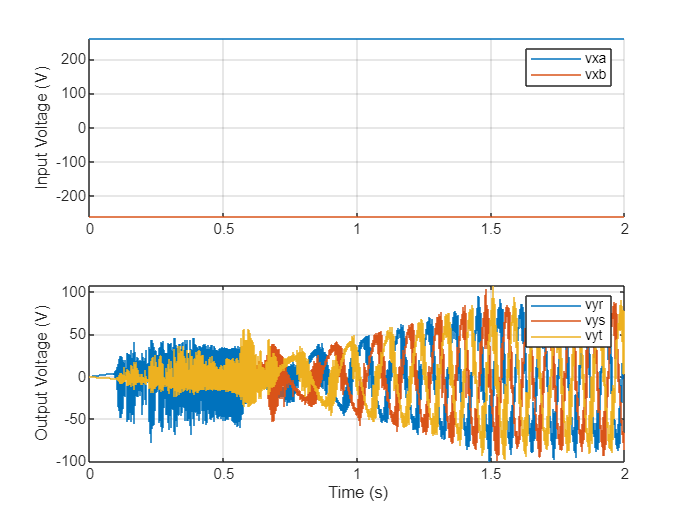

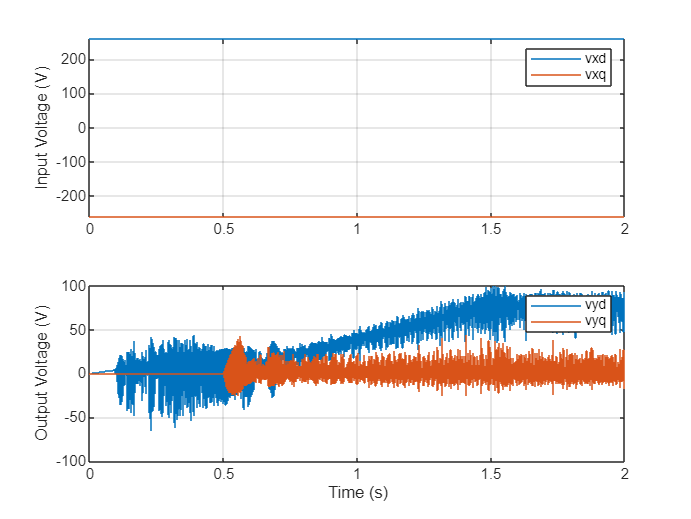

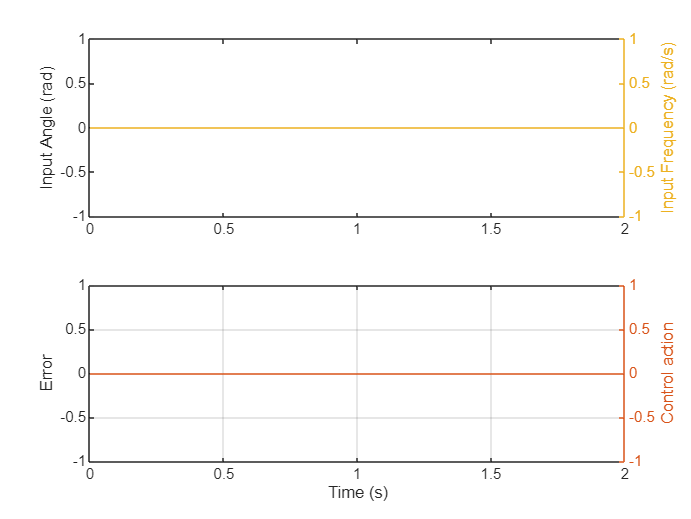

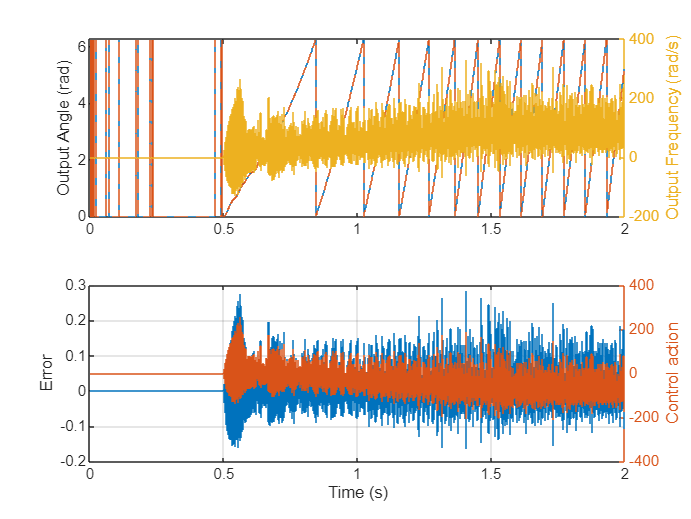

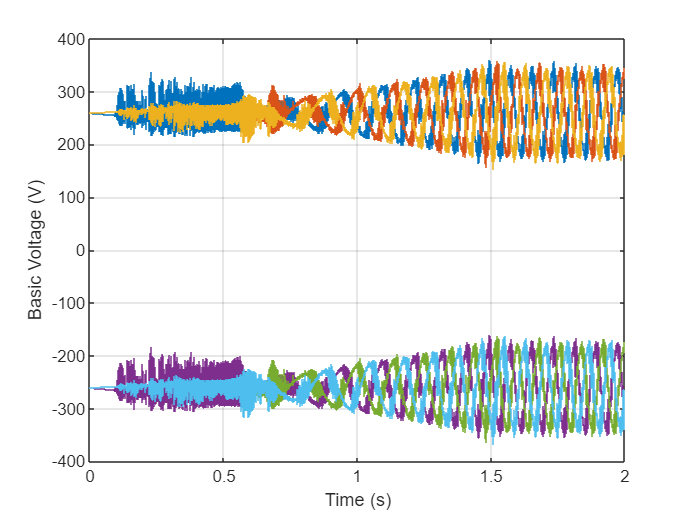

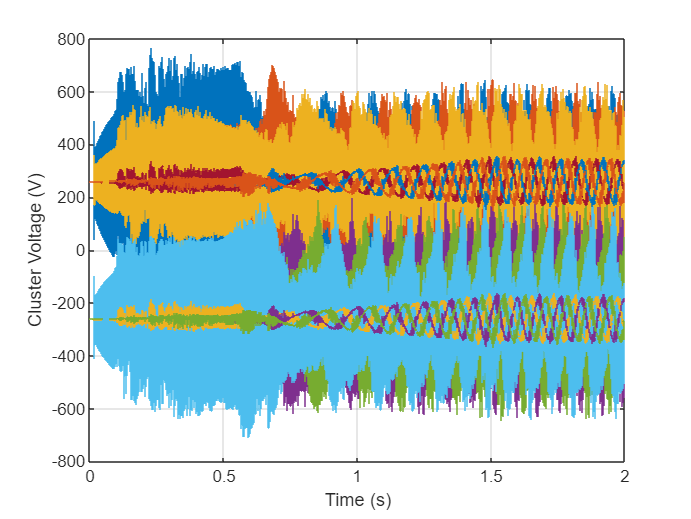

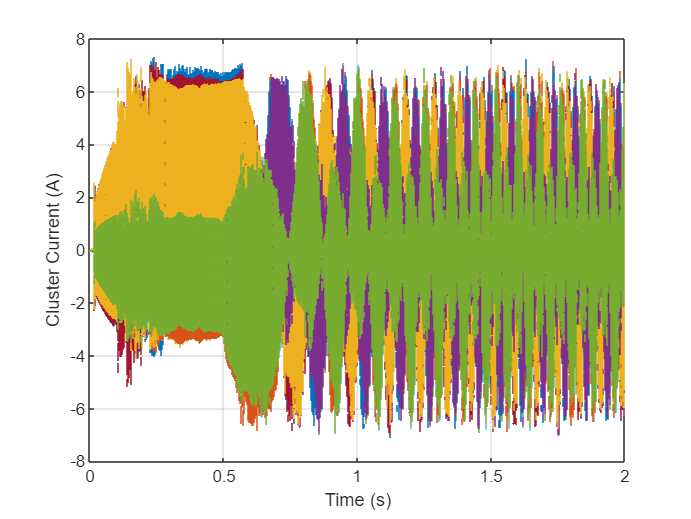

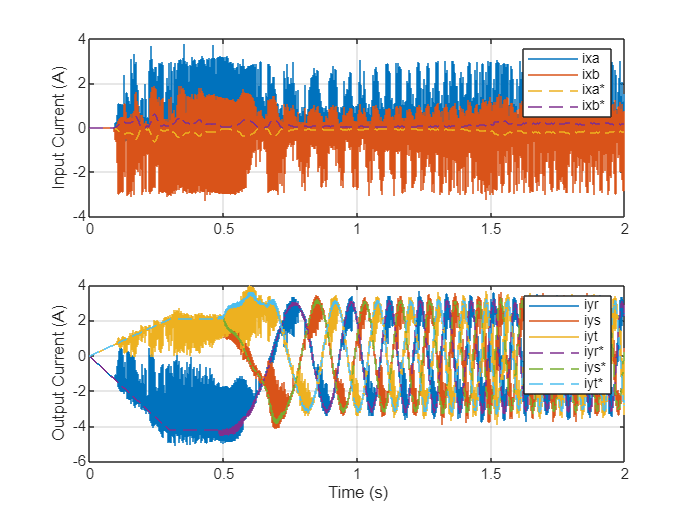

save_experiment = false;
run('Plot.mlx')